addpath(genpath('helpers'));
addpath(genpath('libraries/buzcode/'));


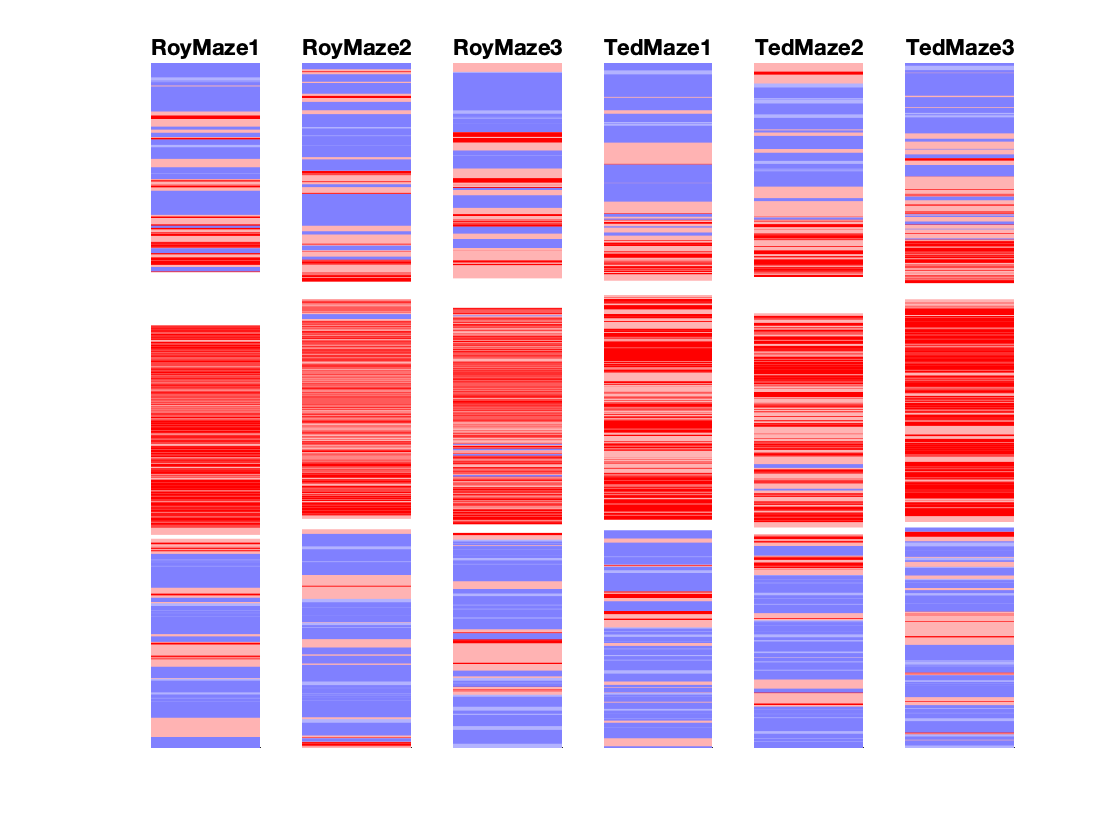

active_num_experiments = length(active_experiment_names);

plottingOptions.orientation = 'vertical';
% plottingOptions.orientation = 'horizontal';
plottingOptions.vertical_state_mode = 'combined';
% plottingOptions.plot_variable = 'behavioral_epoch';
plottingOptions.plot_variable = 'behavioral_state';
    
fig = figure();

% Loop through each experiment:
for expt_index = 1:active_num_experiments
    expt_info.index = expt_index;
    expt_info.name = active_experiment_names{expt_index};
    
    across_experiment_results{expt_index}.active_processing.definitions.behavioral_epoch.classColors = [0.0, 0.5, 0.0
               0.2, 1.0, 0.2
               0.0, 0.2, 0.0];
    
    across_experiment_results{expt_index}.active_processing.definitions.behavioral_state.classColors = [0.5, 0.5, 1.0
               0.7, 0.7, 1.0
               1.0, 0.7, 0.7
               1.0, 0.0, 0.0];

    if strcmpi(plottingOptions.orientation, 'horizontal')
        subplot(active_num_experiments, 1, expt_index);
    else
        subplot(1, active_num_experiments, expt_index);
    end
    [ax] = fnPlotStateDiagram(across_experiment_results{expt_index}.active_processing, plottingOptions);
    title(expt_info.name)
end